# Examples 7.4 and 7.5: Comparing Investment Options

Note: this script reproduces Examples 7.4 and 7.5 (Section 7.2) of **Statistics for Chemical Engineers**: the net present value (NPV) of two investments with random returns. Victor Z UW-Madison, 2023 npv comparison

clc; clear all; close all hidden; format short

## NPV of the two investments (Example 7.4)

compare investment strategies

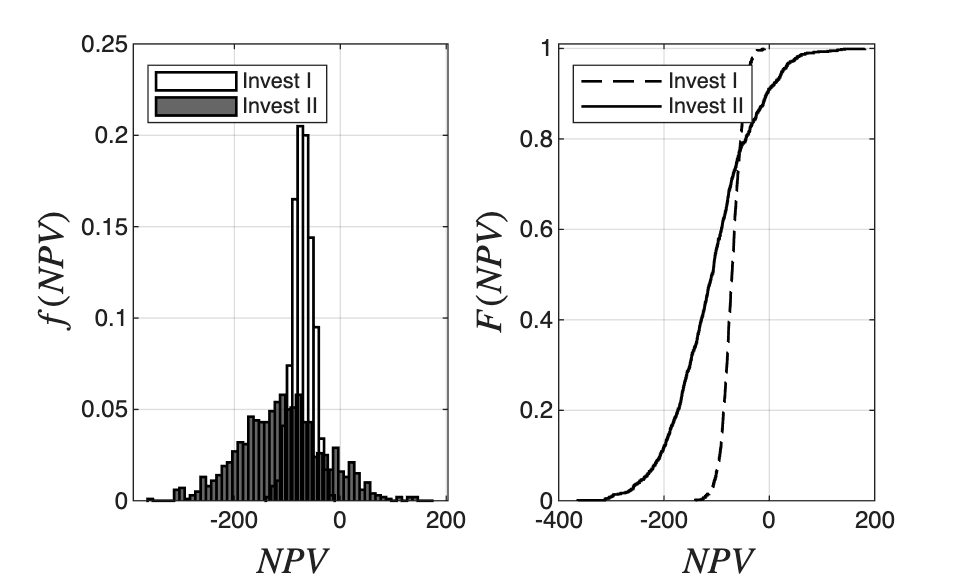

rng(0)

N=1000;  % number of scenarios
ir=0.05; % interest rate

% evaluate investment 1
C1=25;
ROI1=normrnd(0.5,0.1,N);
for i=1:N
    NPV1(i) = C1 - ROI1(i)*C1*(1-(1+ir)^(-10))/ir;
end

% evaluate investment 2
C2=50;
ROI2=normrnd(0.4,0.2,N);
for i=1:N
    NPV2(i)= C2 - ROI2(i)*C2*(1-(1+ir)^(-10))/ir;
end

% lets compare pdfs of NPV
figure(1)

subplot(1,2,1)
lb=min(NPV1); ub=max(NPV1); nb=10; db=(ub-lb)/nb;
histogram(NPV1,lb:nb:ub,'Normalization','probability','EdgeColor','black','FaceColor','white','LineWidth',1)
xlabel('$NPV$','Interpreter','latex','FontSize',14)
ylabel('$f(NPV)$','Interpreter','latex','FontSize',14)


hold on; grid on;

lb=min(NPV2); ub=max(NPV2); nb=10; db=(ub-lb)/nb;
histogram(NPV2,lb:nb:ub,'Normalization','probability','EdgeColor','black','FaceColor','black','LineWidth',1)

legend('Invest I', 'Invest II','Location','northwest')

% lets compare cdfs of NPV
subplot(1,2,2)
[F1,t]=ecdf(NPV1);
stairs(t,F1,'LineWidth',1,'Color','black','LineStyle','--')
xlabel('NPV')
ylabel('F(NPV)') 
hold on; grid on;
[F2,t]=ecdf(NPV2);
stairs(t,F2,'LineWidth',1,'Color','black','LineStyle','-')
xlabel('$NPV$','Interpreter','latex','FontSize',14)
ylabel('$F(NPV)$','Interpreter','latex','FontSize',14)
legend('Invest I', 'Invest II','Location','northwest')
axis([-400 200 0 1.01])
print -depsc -r1200 ch7_comparison_NPV.eps

## Risk measures (Example 7.5)

analyze summarizing statistics

% get expected value
EV1=mean(NPV1)

EV1 = -70.8917

EV2=mean(NPV2)

EV2 = -109.0487


% get SD
SD1=std(NPV1)

SD1 = 19.2844

SD2=std(NPV2)

SD2 = 79.2889


% get worse case
WC1=max(NPV1)

WC1 = -9.1293

WC2=max(NPV2)

WC2 = 181.4132


% get best case
BC1=min(NPV1)

BC1 = -140.6003

BC2=min(NPV2)

BC2 = -363.7083


% VaR (quantile)
Q1 =quantile(NPV1,0.9)

Q1 = -46.6998

Q2 =quantile(NPV2,0.9)

Q2 = -4.9351


% CVaR
loc = NPV1 >= Q1;
CVaR1 = mean(NPV1(loc))

CVaR1 = -37.5307


loc = NPV2 >= Q2;
CVaR2 = mean(NPV2(loc))

CVaR2 = 34.8100


% probability of loss
loc = NPV1 > 0;
Prob1 = 100*sum(loc)/N

Prob1 = 0


loc = NPV2 > 0;
Prob2 = 100*sum(loc)/N

Prob2 = 9


% probability of gain
loc = NPV1 <= -100;
Prob1 = 100*sum(loc)/N

Prob1 = 6.4000


loc = NPV2 <= -100;
Prob2 = 100*sum(loc)/N

Prob2 = 55.9000

## Deterministic NPV

assuming deterministic

% evaluate investment 1
C1=25;
ROI1=0.5;
NPV1det =  C1 - ROI1*C1*(1-(1+ir)^(-10))/ir

NPV1det = -71.5217


% evaluate investment 2
C2=50;
ROI2=0.4;
NPV2det =  C2 - ROI2*C2*(1-(1+ir)^(-10))/ir

NPV2det = -104.4347

## Probability of loss versus investment C (t = -100)

determine optimal C such that P(NPV<=t) is high

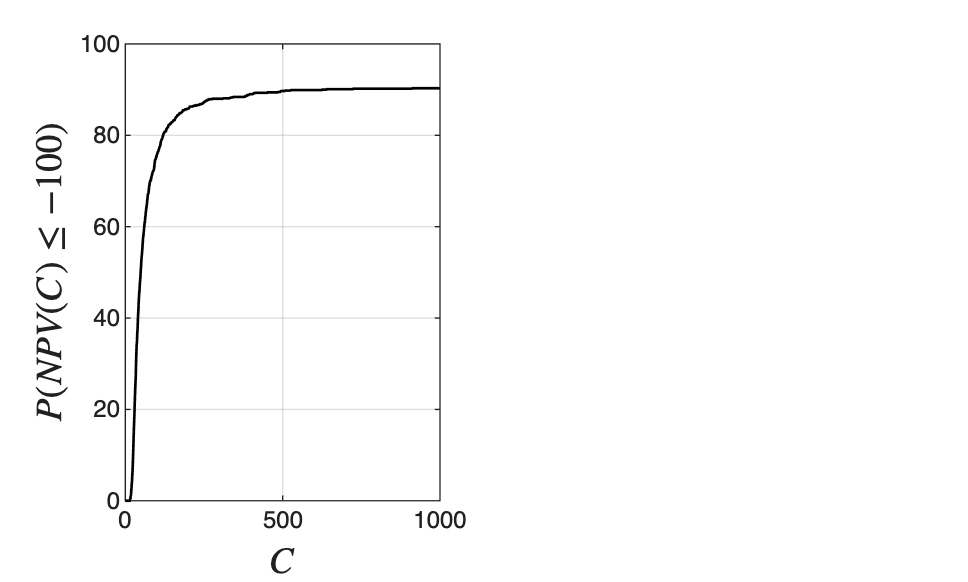

t = -100;

C=linspace(0,1000,1000);

ROI=normrnd(0.4,0.2,N);

for k=1:length(C)

NPV=[];    
for i=1:N
    NPV(i) = C(k) - ROI(i)*C(k)*(1-(1+ir)^(-10))/ir;
end

% probability of loss
loc = NPV <= t;
PNPV(k) = 100*sum(loc)/N;

end

figure(2)
subplot(1,2,1)
plot(C,PNPV,'LineWidth',1,'Color','black','LineStyle','-')
grid on
hold on
xlabel('$C$','Interpreter','latex','FontSize',14)
ylabel('$P(NPV(C)\leq -100)$','Interpreter','latex','FontSize',14)

## Probability of loss versus investment C (t = -500)

determine optimal C such that P(NPV<=t) is high

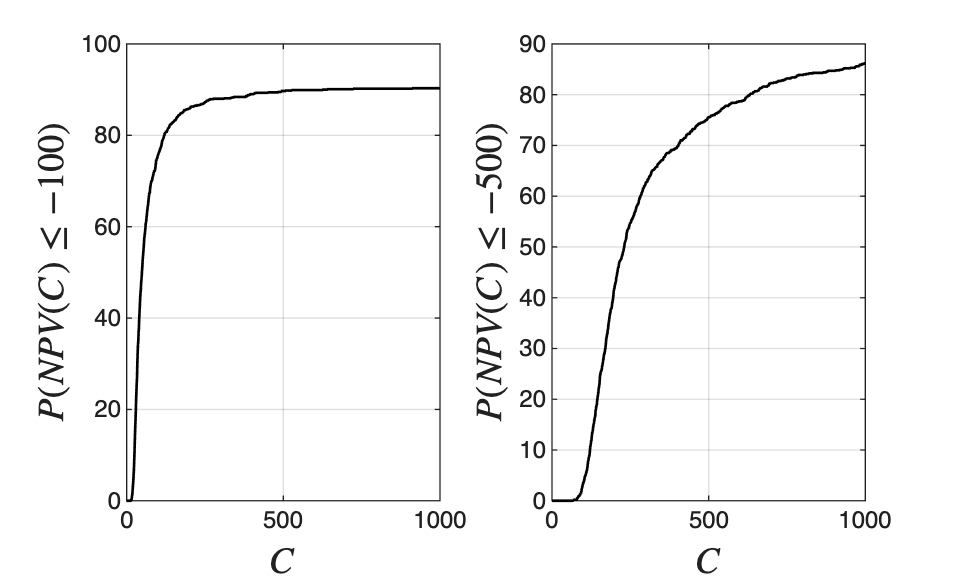

t = -500;

C=linspace(0,1000,1000);

ROI=normrnd(0.4,0.2,N);

for k=1:length(C)

NPV=[];    
for i=1:N
    NPV(i) = C(k) - ROI(i)*C(k)*(1-(1+ir)^(-10))/ir;
end

% probability of loss
loc = NPV <= t;
PNPV(k) = 100*sum(loc)/N;

end

figure(2)
subplot(1,2,2)
plot(C,PNPV,'LineWidth',1,'Color','black','LineStyle','-')
grid on
hold on
xlabel('$C$','Interpreter','latex','FontSize',14)
ylabel('$P(NPV(C)\leq -500)$','Interpreter','latex','FontSize',14)
print -depsc ch7_invest_comparison.eps

## Note

As in the book, a risk-averse decision-maker prefers the first investment (no chance of losing money), while a risk-taker may accept a 9% chance of loss for the chance of large gains.